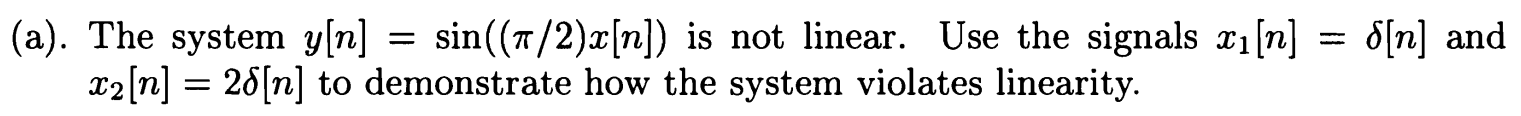

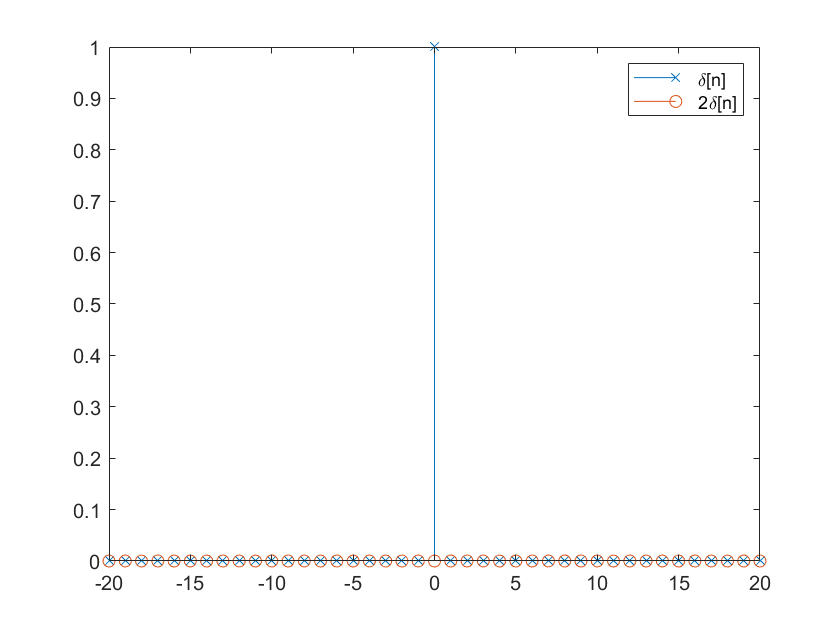

n = -20:20;
x1 = impu(n);
x2 = 2.*impu(n);
y1 = sys_pa(x1);
y2 = sys_pa(x2);
fa = figure;
figure(fa);
stem(n, y1, 'x');
hold on
stem(n, y2);
hold on
legend('\delta[n]', '2\delta[n]');
hold off;

The system is not linear. Because  $x_2$ = 2 * $x_1$ but at n=0, $S(x_2)$ which is 0 is not two times of $S(x_1)$ which is 1. 

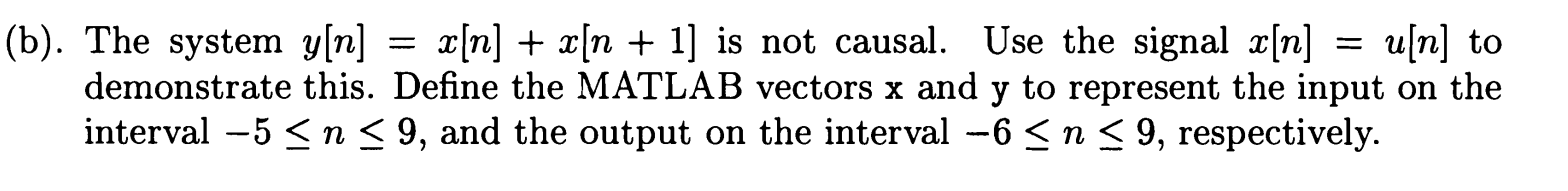

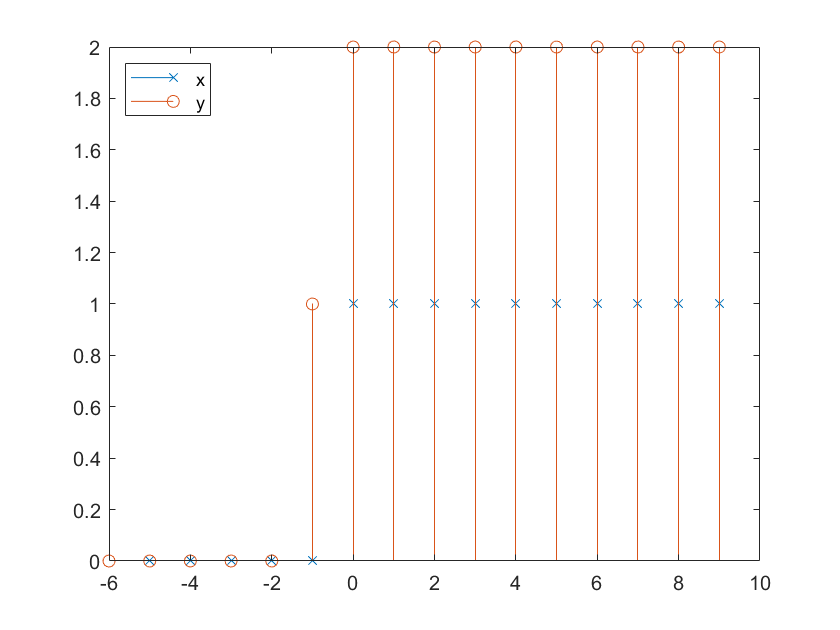

fb = figure;
figure(fb);
n1 = -5:9;
n2 = -6:10;
x = step(n1);
x2 = step(n2);
y = sys_pb(x2);
stem(-5:9, x, 'x');
hold on
stem(-6:9, y);
hold on
legend('x', 'y', 'Location','northwest');
hold off

Differential equation of y only has linear constant coefficient and no additional constant. And y[-1] is not 0. So, the system is not causal.

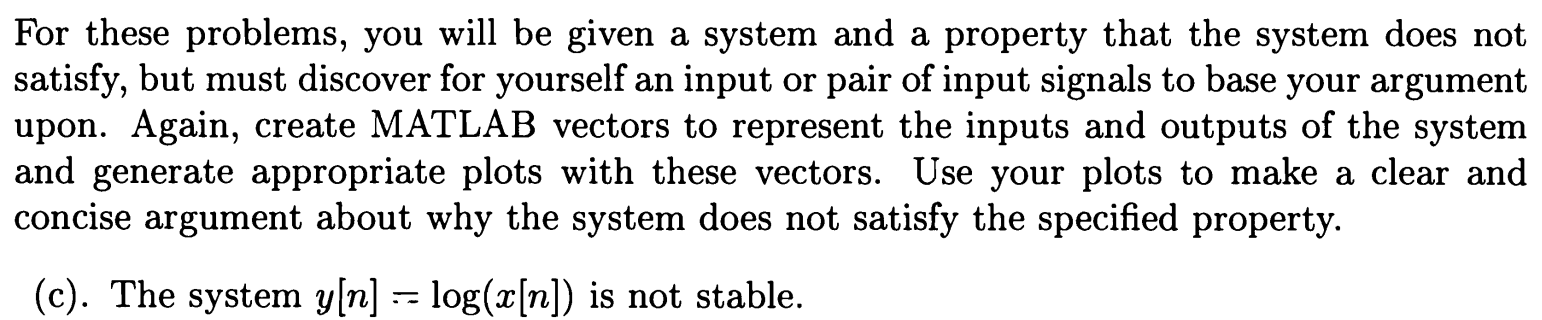

let $
    \[ x[n] = \begin{cases} 
          1/e^n & x\geq 0 \\
          1/e^{-n}& x<0 
       \end{cases}
    \]
$. x[n] has bound. its value is always larger than 0 and always less than 1 for every n. But when abs(n) becomes larger to infinite, y[n] = log(x[n]) = -abs(n) will be minus infinite. So, y[n] has no bound. So, the system is not stable.

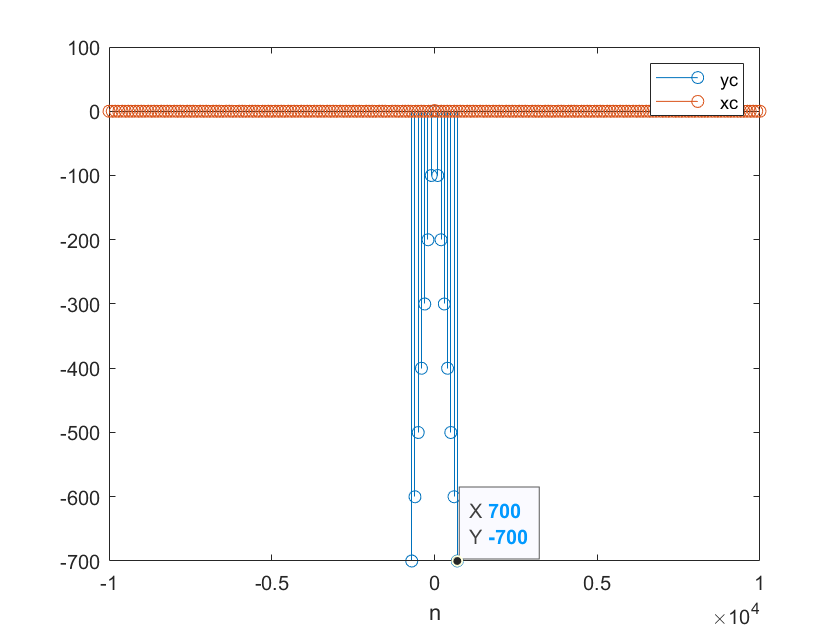

n = -10000:100:10000;
xc = arrayfun(@(x) input_c(x), n);
yc = sys_pc(xc);
fc = figure;
figure(fc);
stem(n,yc);
hold on
stem(n, xc);
hold on
legend('yc', 'xc');
xlabel('n')
xlim([-10000 10000])
ylim([-700 100])
ax = gca;
chart = ax.Children(2);
datatip(chart,700,-700);
hold off

 According to figure, xc has bound, and yc = -abs(n) which has no bound. So, the system is not stable.

let x[n] = n. Then x[n] is distinct. Get the output of the system and see whether the output is distinct.

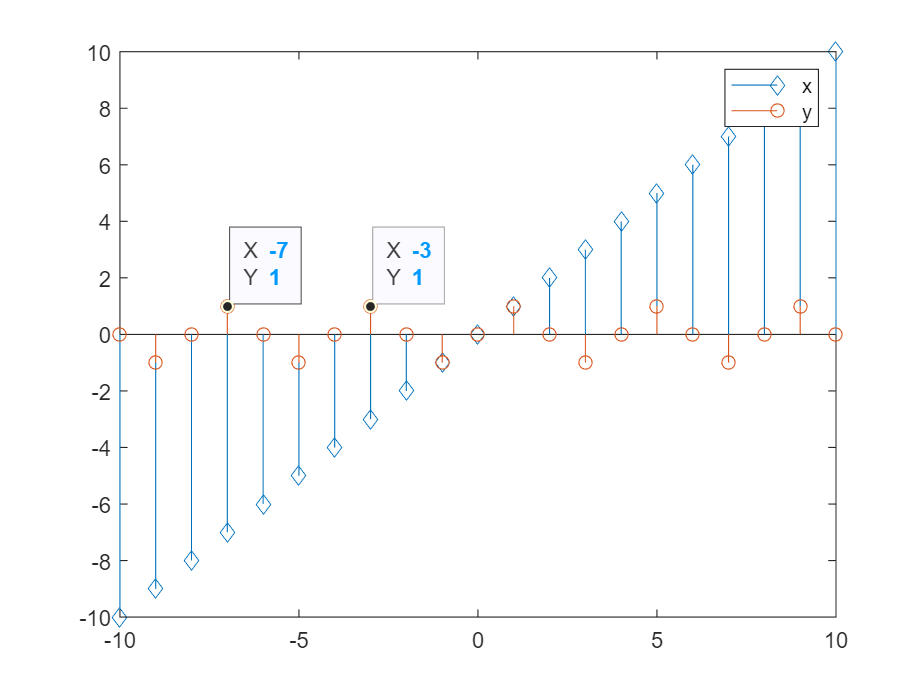

n = -10:10;
yd = sys_pa(n);
fd = figure;
figure(fd);
stem(n, n, 'd');
hold on
stem(n, yd);
hold on
legend('x', 'y');
ax2 = gca;
chart2 = ax2.Children(1);
datatip(chart2,-3,1);
datatip(chart2,-7,1);
hold off

The input x is distinct but the output y is not distinct for example y[-7] = y[-3]. So, the system is not invertible.

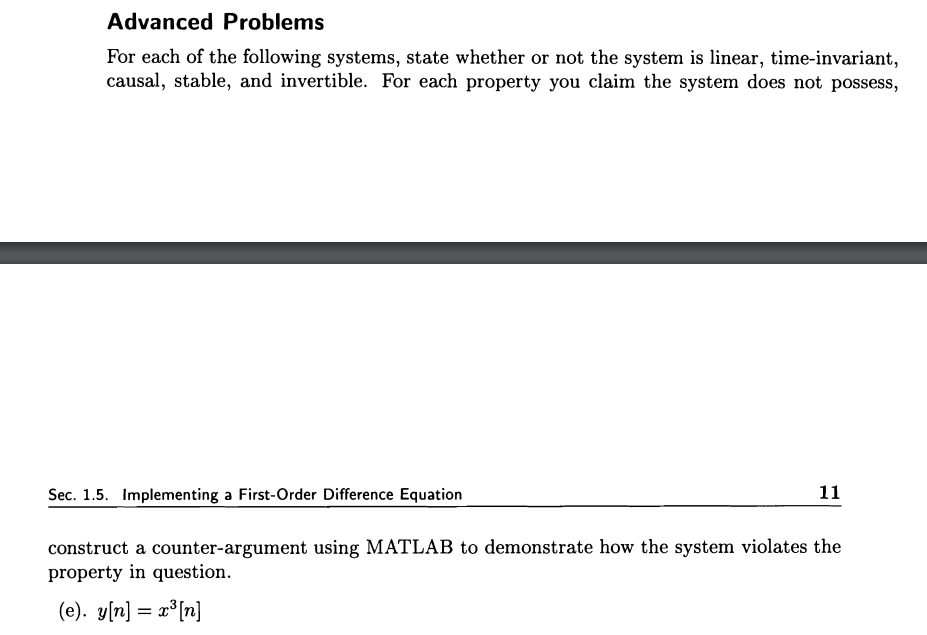   

(e) not linear 

let x[n] = n;

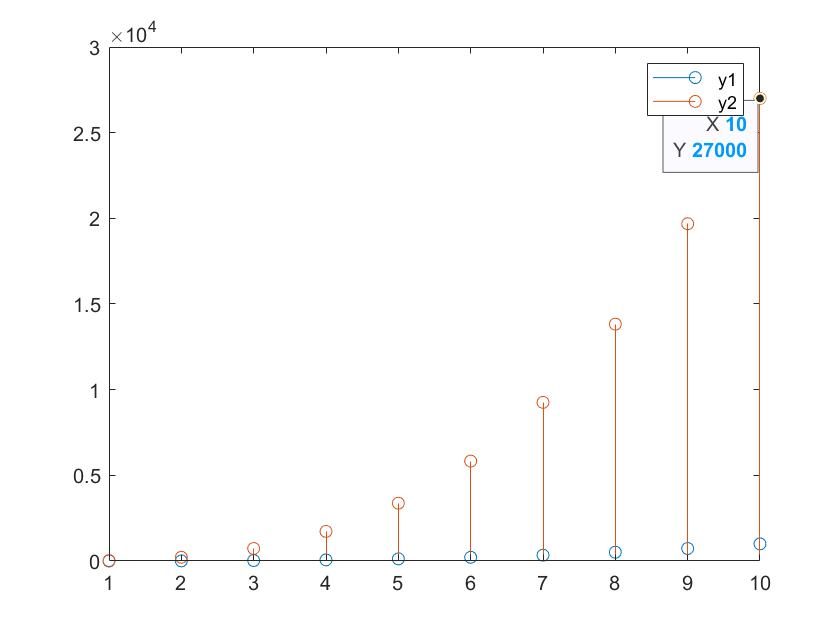

n = 1:10;
x1 = n;
x2 = 3.*n;
y1 = x1.^3;
y2 = x2.^3;
fe = figure;
figure(fe);
stem(n, y1);
hold on
stem(n, y2);
hold on
legend('y1', 'y2');
hold off

According to the stem, value of y2 is not 3 times of y1, so the system is not linear.

(f) not time-invariant. let x[n] = n;

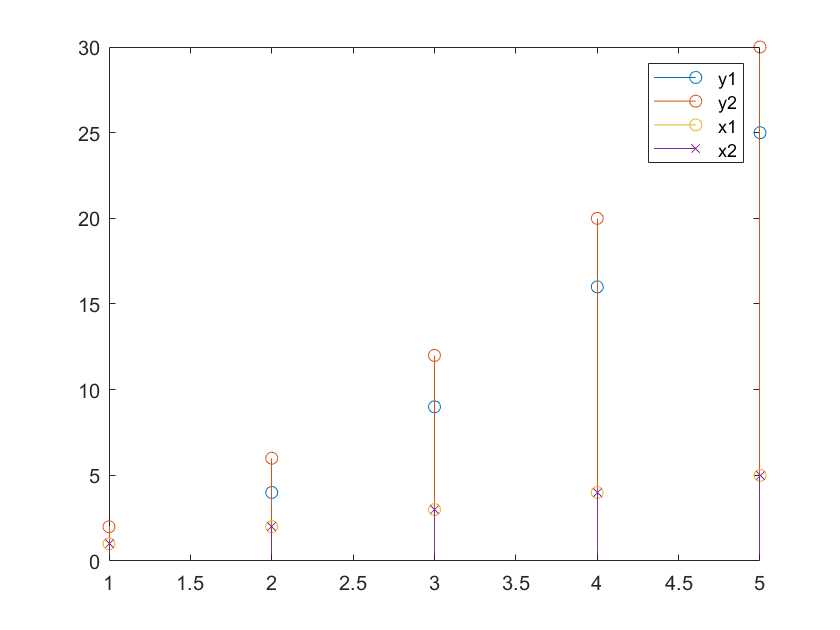

n = 1:6;
x1 = n;
x2 = n-1;
y1 = n.*x1;
y2 = n.*x2;
y1_t = y1(1:length(y1)-1);
x1_t = x1(1:length(x1)-1);
y2_t = y2(2:length(y2));
x2_t = x2(2:length(x2));
ff = figure;
figure(ff);
stem(1:5, y1_t);
hold on
stem(1:5, y2_t);
hold on
stem(1:5, x1_t);
hold on
stem(1:5, x2_t, 'x');
legend('y1', 'y2', 'x1', 'x2');
hold off

$x_2[n]$ = $x_1[n-1]$, but $y_2[n]$ is not equal to $y_1[n-1]$. So, the system is not time-invariant.

(f) not stable. let x[n] = u(n) (step). x[n] has bound, it's absolute value is not biiger than 1. But y[n] = n when n>=0 which has no bound.

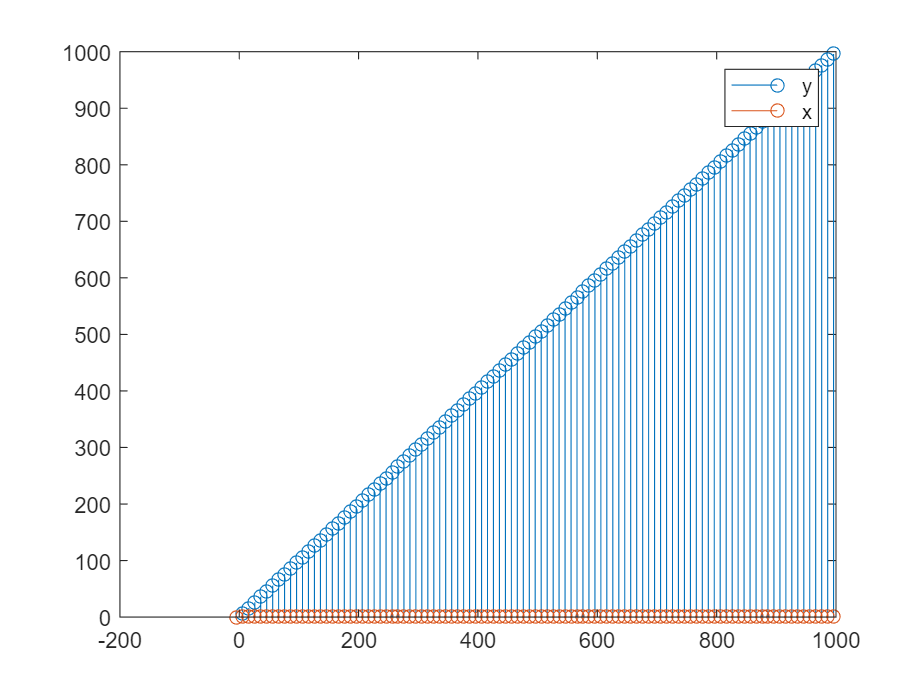

n = -4:10:1000;
x = step(n);
y = n.*x;
ff_s = figure;
figure(ff_s);
stem(n, y);
hold on
stem(n, x);
hold on
legend('y', 'x');
hold off

y has no bound, so the system is not stable.

(f) not invertible. let x[n] = $1/n$(n>0) then y = 1 for every n. So, the system is not invertible.

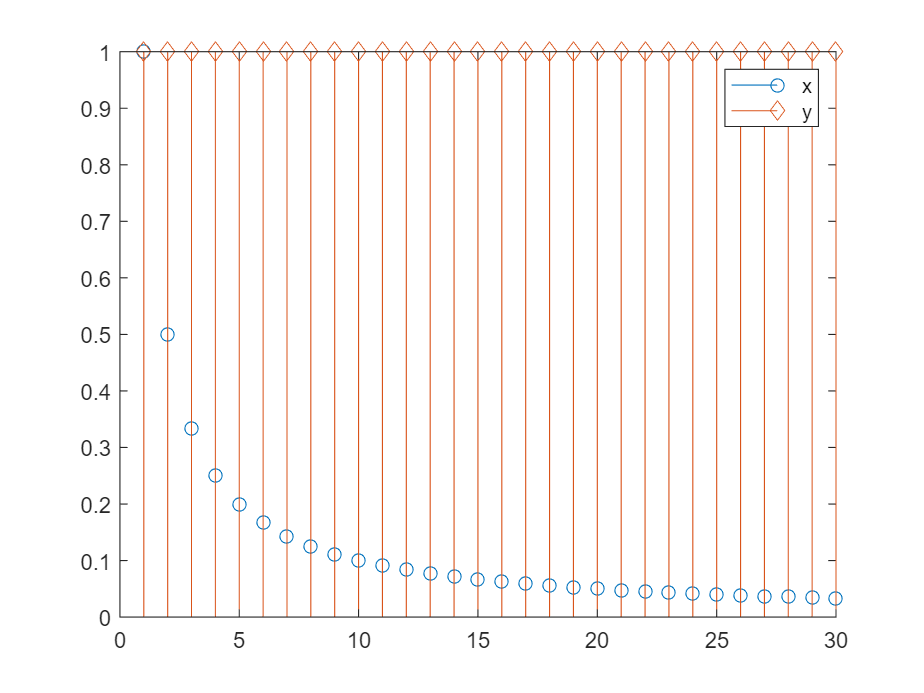

n = 1:30;
x = 1./n;
y = n.*x;
ff_i = figure;
figure(ff_i);
stem(n, x);
hold on
stem(n, y, 'd');
hold on
legend('x', 'y');
hold off

x is distinct, but y is not. So, the system is not invertible.

(g) not time-invariant. 

let $x_1[n]$ = n, $x_2[n]$ = $x_1[n-1]$ = n-1

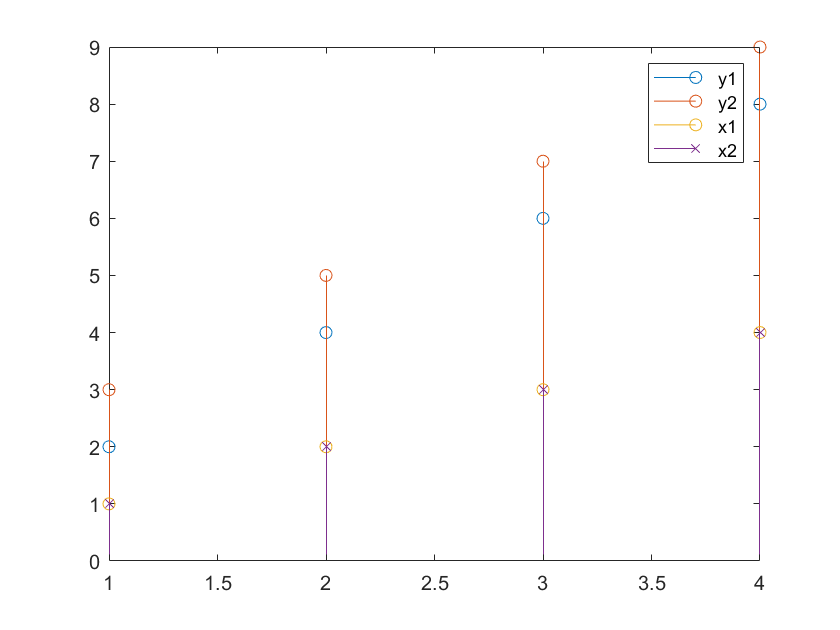

true_n = 1:5;
n =1:11;
x1 = n;
x2 = n-1;
y1 = x1(2.*true_n);
y2 = x2(2.*true_n);
y1_t = y1(1:length(y1)-1);
y2_t = y2(2:length(y2));
x1_t = x1(1:length(true_n)-1);
x2_t = x2(2:length(true_n));
fg_ti = figure;
figure(fg_ti);
true_n = true_n(1:length(true_n)-1);
stem(true_n, y1_t);
hold on
stem(true_n, y2_t);
hold on
stem(true_n, x1_t);
hold on
stem(true_n, x2_t, 'x');
hold on
legend('y1', 'y2', 'x1', 'x2');
hold off

 $x_1[n-1]$  = $x_2[n]$ but $y_1[n-1]$ != $y_2[n]$. So, the system is not time-invariant.

(g) not causal.

let $x_1[n]$ = [1 2 3 4 5 6 7 8 9 10]

let $x_2[n]$ = [1 2 3 4 5 11 12 13 14 15]

for n<=5 $x_1[n]$ = $x_2[n]$, if the system is causal, $y_1[n]$ should be equals to $y_2[n]$ in this interval.

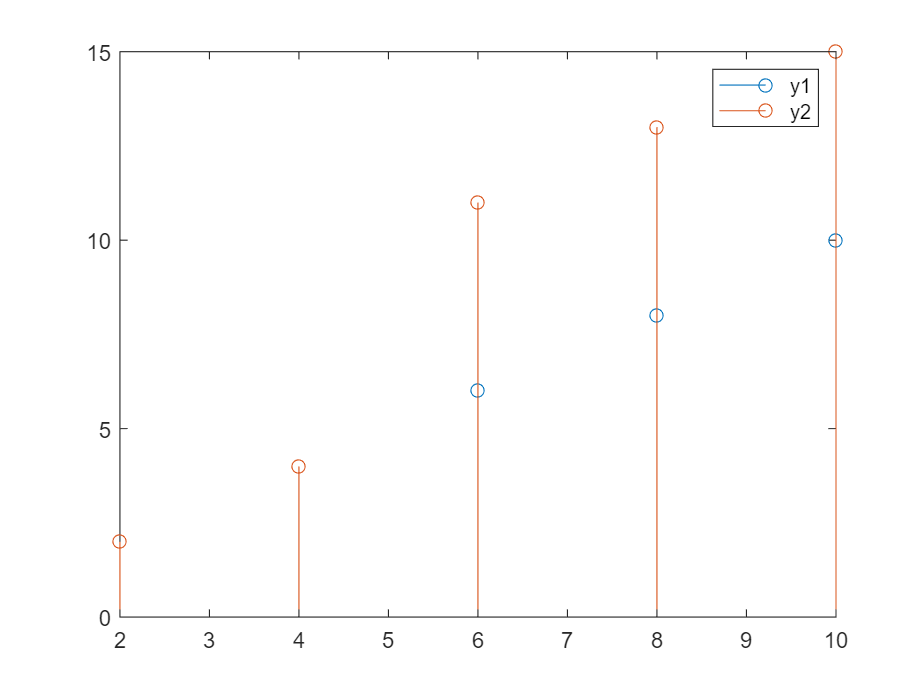

x1 = [1 2 3 4 5 6 7 8 9 10];
x2 = [1 2 3 4 5 11 12 13 14 15];
n_t = 1:5;
n = 2.*n_t;
y1 = x1(n);
y2 = x2(n);
fg_c = figure;
figure(fg_c);
stem(n, y1);
hold on
stem(n, y2);
hold on;
legend('y1', 'y2');
hold off

y1 != y2. So, the system is not causal.

function [y] = sys_pa(x)
    y = sin((pi/2) .* x);
end

function [y] = sys_pb(x)
    xt = [x(2:length(x)) 0];
    y = x + xt;
    y = y(1:length(y)-1);
end
 
function [y] = impu(n)
    y = (n==0);
end

function [y] = step(n)
    y = (n>=0);
end

function [y] = sys_pc(x)
    y = log(x);
end

function [x] = input_c(n)
    if(n>=0)
        x = 1./exp(n);
    else
        x = 1./exp(-n);
    end
end